# Inefficiency metric

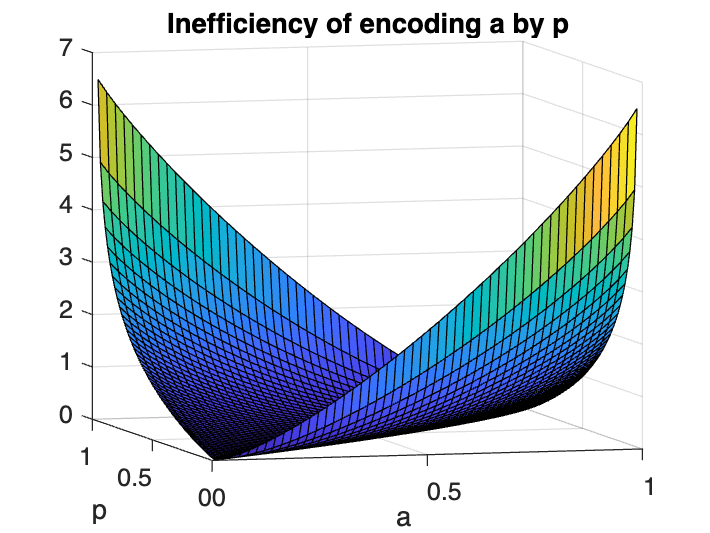

% The inefficiency of using a code designed for p
% when it's actually distributed as a (binary)
[a, p] = ndgrid(linspace(0.01, 0.99, 50));
surf(a, p, -(a .* (log2(p) - log2(a)) + (1- a) .* (log2(1-p) - log2(1-a))));
xlabel('a');
ylabel('p');
view([-15.55 6.65]);
title("Inefficiency of encoding a by p");

## Example from a Joint Distribution

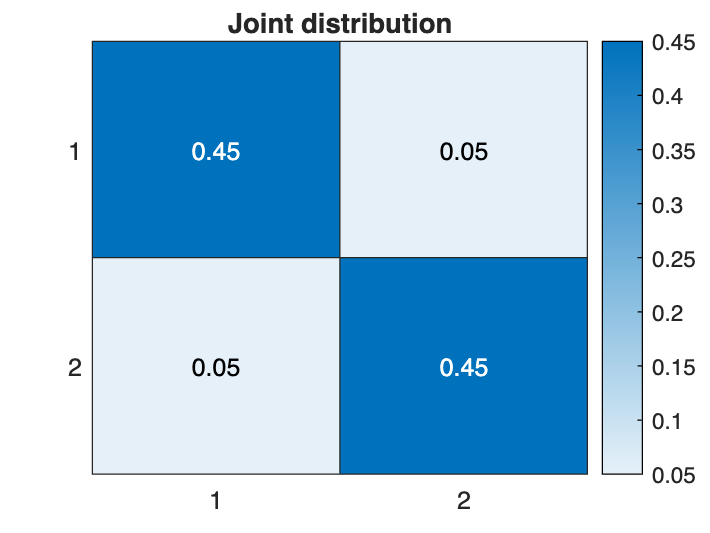

% Joint distribution. Row indexes alice's action
% columns index bob's. 1 is "raise hand" or "1".
% jDist = rand(2,2);
jDist = [0.45 0.05; 0.05 0.45];
jDist = jDist / sum(jDist, 'all');
heatmap(jDist);
title("Joint distribution")


% Probability outputs on a particular sample
aSampP = 0.75 % alice sample probability

aSampP = 0.7500

bSampP = 0.75 % bob sample probability

bSampP = 0.7500

## Self coding inefficiency

pA = sum(jDist, 1);
pA = pA(1)

pA = 0.5000

pB = sum(jDist, 2);
pB = pB(1)

pB = 0.5000


ineffA = - (aSampP * (log2(pA) - log2(aSampP)) + (1-aSampP) * (log2(1- pA) - log2(1 - aSampP)))

ineffA = 0.1887

ineffB = - (bSampP * (log2(pB) - log2(bSampP)) + (1-bSampP) * (log2(1-pB) - log2(1- bSampP)))

ineffB = 0.1887

## Cross (conditional) coding inefficiency

ineffAcondB = - (aSampP .* (log2(jDist(1,:)/pB) - log2(aSampP)) + (1-aSampP) .* (log2(jDist(2,:)/pB) - log2(1-aSampP)))

ineffAcondB =     0.1332    1.7182


ineffBCondA = - (bSampP .* (log2(jDist(:,1)/pA) - log2(bSampP)) + (1-bSampP) .* (log2(jDist(:,2)/pA) - log2(1-bSampP)))

ineffBCondA =     0.1332
    1.7182
